## MATLAB Live scripts demonstating aspects of Optimal Interpolation.

#### The methodology follows Chapter 4, *The spatial analysis of data fields,* in: Thompson, R.E. and W. J. Emery (2014) "Data analysis methods in physical oceanography," Elsevier, [https://doi.org/10.1016/C2010-0-66362-0](https://doi.org/10.1016/C2010-0-66362-0)

#### John L. Wilkin - jwilkin@rutgers.edu

## Exercise 3: SST patterns of Tropical Instability Waves in the eastern Equatorial Pacific - Infrared SST observations from Low Earth Orbiting (LEO) satellites

For an overview of the dynamics of Tropical Instability Waves, see: Willett, C.S., Leben, R.R. and Lavín, M.F., 2006. Eddies and tropical instability waves in the eastern tropical Pacific: A review. *Progress in Oceanography*, *69*(2-4), pp.218-238. [https://doi.org/10.1016/j.pocean.2006.03.010](https://doi.org/10.1016/j.pocean.2006.03.010) 

### This live script parallels Exercise 2, but uses actual ocean observatios acquired by infrared imagers on LEO satellites during November 2022. 

%

#### Load Level-3 gridded example data set and subsample spatially to create a set of pseudo observations

% Data downloaded on 11 February, 2023, from NASA PO.DAAC Dataset catalog 
% ID ACSPO-L3S-LEO-AM-v2.80 
% The data file contains 10 days of data centered on 2022-11-13
f = 'L3S_LEO_ACSPO_SST_20221113_10day.nc';

% These are very high resolution 1/50 arc degree lon/lat (~2.2 km) data. 
% To make the OI manageable, decimate the data on load by factor of s in
% both horizontal coordinates

s = 40;
leo.lon = ncread(f,'lon',1,Inf,s);
leo.lat = ncread(f,'lat',1,Inf,s);
leo.time = roms_get_time(f,'time');
for v = {'sea_surface_temperature','sses_bias','quality_level'}
  vname = char(v);
  leo.(vname) = ncread(f,vname,[1 1 1],[Inf Inf Inf],[s s 1]);
end
[leo.lon,leo.lat] = ndgrid(leo.lon,leo.lat);

% Only accept data that meets quality_level flag = 5 (see NetCDF global 
% attributes for more information on quality_level)
leo.sea_surface_temperature(leo.quality_level~=5) = NaN;

% Apply sses_bias correction (see NetCDF global attributes for more 
% information on sses_bias)
leo.sea_surface_temperature = leo.sea_surface_temperature-leo.sses_bias;

% Convert Kelvin to Celsius
leo.sea_surface_temperature = leo.sea_surface_temperature-273.15;

#### Choose a day or set of days of data

% K = 6; % K = 6 is 2022-11-12 12:00 UTC 
K = [6 7 8]; % 3 days centered on 2022-11-13
% K = 6
disp("Using data for: ")

Using data for: 


for k=1:numel(K)
  disp(datestr(leo.time(K(k))))
end

12-Nov-2022 12:00:00
13-Nov-2022 12:00:00
14-Nov-2022 12:00:00



data = leo.sea_surface_temperature(:,:,K(1));
valid = ~isnan(data);
x = leo.lon(valid);
y = leo.lat(valid);
data = data(valid);
% if more than one day
for k=2:numel(K)
  next = leo.sea_surface_temperature(:,:,K(k));
  valid = ~isnan(next);
  x = cat(1,x,leo.lon(valid));
  y = cat(1,y,leo.lat(valid));
  data = cat(1,data,next(valid));
end
disp("OI will be performed using "+int2str(numel(data))+" observations")

OI will be performed using 4789 observations


#### Plot the data

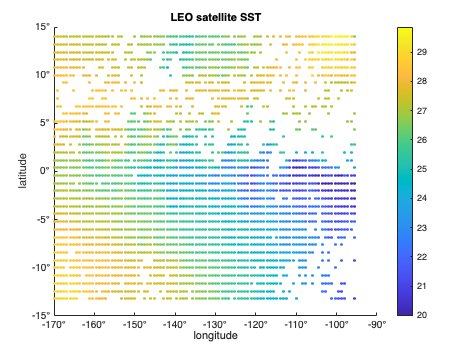

scatter(x,y,10,data,'o','filled')
colorbar
title("LEO satellite SST")
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')

drawnow

#### Prepare for Optimal Interpolation

% save the mean of the data for later
datam = mean(data);

% compute data anomaly from the mean - optimal interpolation works on the anomaly
dataa = data - datam;

% Create matrices that repeat the observation coordinates: columns 
% of x, and rows of y. X-X' and Y-Y' will be all possible distance 
% combinations between pairs of points
X = repmat(x,[1 length(y)]);
Y = repmat(y',[length(x) 1]);
Rdd = sqrt((X-X').^2+(Y-Y').^2);

% Set the covariance length scale in degrees lon/lat
a = 0.9;

% Set the signal standard deviation SQUARED
sstd = 0.5;
ssq = sstd^2;

% Set the observation error standard deviation (IR SST +/- 0.4 degC)
e = 0.3;

#### Build the data-data covariance matrix

Rddona = Rdd/a;
Cdd0 =  exp(-Rddona).*(1+Rddona+(Rddona.^2)/6-(Rddona.^3)/6);

% Add error variance nomalized by signal variance along the diagonal
lambda = e^2/ssq;
Cddf = Cdd0 + lambda*eye(size(Cdd0));

disp("A noise to signal variance ratio of "+num2str(e^2/ssq,3)...
  +" will be added to the diagonal of the data-data covariance matrix")

A noise to signal variance ratio of 0.36 will be added to the diagonal of the data-data covariance matrix


#### Build the model-data covariance function

% Map to same grid as the pseudo data example
if ~exist('LON','var')
  load rtofs2.mat
  [LON,LAT] = ndgrid(rt.lon,rt.lat);
end

% Get distances between every grid point and every data point
Xgrid = repmat(LON(:),[1 numel(y)]);
Xdata = repmat(x(:),[1 numel(LAT)]);
Ygrid = repmat(LAT(:)',[length(x) 1]);
Ydata = repmat(y',[numel(LAT) 1]);
Rmd = sqrt((Xgrid-Xdata').^2+(Ygrid'-Ydata).^2);

% Evaluate the normalized covariance using the chosen covariance function
Rmdona = Rmd/a;
Cmd =  exp(-Rmdona).*(1+Rmdona+(Rmdona.^2)/6-(Rmdona.^3)/6);

#### Perform the Optimal Interpolation

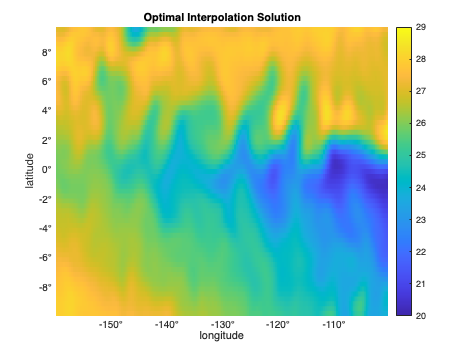

% Formally, OI evaluates Cmd*inv(Cdd)*data, but it is faster to use a
% Matrix Left Divide (see Matlab help mldivide) 
Da = Cmd*(Cddf\dataa);
Da = reshape(Da,size(LON));

% restore the mean
DOI = datam + Da;

% Plot the interpolated field
pcolor(LON,LAT,DOI)
shading flat
caxis([20 29])
colorbar
title("Optimal Interpolation Solution")
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')

drawnow

#### Compute expected error estimate

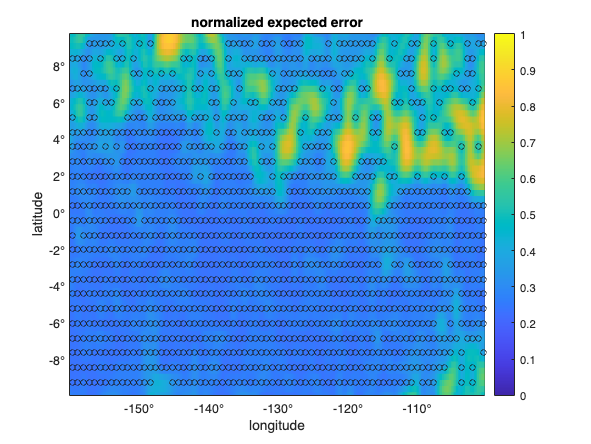

oierrornorm = diag(1-Cmd*inv(Cddf)*Cmd');
oierrornorm = sqrt(oierrornorm);
oierrornorm = reshape(oierrornorm,size(LON));

% Plot a map of the normalized OI error
pcolorjw(LON,LAT,oierrornorm); caxis([0 1])
colorbar
hold on
han = scatter(x,y,20,'w','o','MarkerEdgeColor','w');
han.MarkerEdgeColor = 0.1*[1 1 1];
hold off
title("normalized expected error")
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')

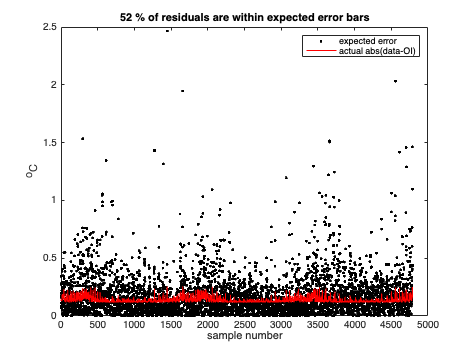


% Calculate expected error at the data locations, but this time multiply 
% by signal variance to get dimensional values
% oierror0 = ssq*diag(1-Cdd0*inv(Cddf)*Cdd0');
oierror0 = ssq*diag(1-Cdd0*(Cddf\Cdd0'));
oierror0 = sqrt(oierror0);

% Plot OI error in comparison to residuals
D0 = Cdd0*(Cddf\dataa);
plot(1:length(dataa),abs(D0-dataa),'k.',1:length(dataa),oierror0,'r-')
legend("expected error","actual abs(data-OI)")
within_limits = find(dataa<(D0+oierror0) & dataa>(D0-oierror0));
xlabel('sample number')
ylabel('^oC')
titlestr = int2str(round(100*length(within_limits)/length(dataa)))+...
  " % of residuals are within expected error bars";
title(titlestr)

disp(titlestr+newline+" (expect 68% for normally distributed random variable)")

52 % of residuals are within expected error bars
 (expect 68% for normally distributed random variable)


drawnow